# Internal Flow

[⇦ Return to the navigation page](matlab:run("Navigation.mlx"))

[Image of house network with 2 sinks]

## **Before you get started**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build somgit e familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Ideal vs. non-ideal internal flow

In [PressureVelocity.mlx](matlab:open('./PressureVelocity.mlx')), we introduced Bernoulli's equation:


$$\frac{P}{\rho g} + \frac{v^2}{2 g} + h = H_0=\text{Constant}
\qquad
(\text{Head-loss form})$$



$$P+
\frac{1}{2}\rho v^2+
\rho g z= \text{Constant} 
\qquad
(\text{Pressure form})$$


This relation states that the total pressure, or total energy of the fluid is conserved along a streamline. This is an idealistic view of fluid flow, and particularly for internal flow, the energy is not conserved. Take the example of a house with its plumbing, the energy of the water flowing through the pipe is not entirely conserved from time it enters the house through the main water intake to the time it leaves the house to the sewer system. For example, in every pipe the friction of water against the wall of the pipe dissipates energy and participe in reducing the pressure. Moreover, every elbow, change in diameter, valve, opening etc. are also associated with dissipation of energy. These dissipation of energy is usually refered as head-loss.

[Image of pipe]

## How to estimate head-loss

### Pipe head-loss

The head-loss through a pipe is computed using Darcy-Weisbach equation:


$$H_l = f_D \frac{L}{D}\frac{V^2}{2g}
\qquad
(\text{Head-loss form})$$



$$\Delta P = \rho g H_l
\qquad
(\text{Pressure form})$$


Where $L$ is the length of the pipe, $D$ its diameter, $V$ the v elocity of the flow and $g$ is the local acceleration due to gravity. The coefficient $f_D$ is Darcy's friction factor. This factor depends on the flow regime (laminar or turbulent) and can be determined:

- Reading charts (Moody chart)

- Solving theoritical and empircal expressing of the head loss.

#### Laminar regime

The head-loss in a pipe in laminar regime was determined anatically by Poiseuille:


$$f_D = \frac{64}{\text{Re}}
\qquad
\text{with Re} < 3000$$


The Reynolds number Re is a non-dimensional number representing the that helps in the characterization of the flow regime. For pipe flow, Reynolds number under 3000 are consider to be laminar.


$$\text{Re} = \frac{\rho VD}{\mu}$$


Where $\rho$ is the density of the fluid, $V$ its velocity, and $\mu$ the dynamic viscosity. $D$ a length-scale that depends on the problem considered, commonly the diamater in case of pipe flow.

figure
Re = logspace(0,log10(3000),100);
fD = 64./Re;
loglog(Re,fD,SeriesIndex=1,DisplayName="Laminar Regime")
xlabel("Reynold Number, Re = $\frac{\rho V D}{\mu}$",Interpreter="latex")
ylabel("Friction Factor, $f_D$",Interpreter="latex")

#### Turbulent regime

The head-loss in a pipe in turbulent regime can be determined using the Colebrook-White equation:


$$\frac{1}{\sqrt{f_d}} = -2\log\left(\frac{\epsilon}{3.7D_H}+\frac{2.51}{\text{Re}\sqrt{f_D}} \right)
\qquad
\text{with Re} > 4000$$


In this equation, $\frac{\epsilon}{D_H}$ correspond to the relative roughness of the pipe, $\epsilon$ correspond to the roughness and is expressed in units of length (usually mm or inches). The Colebrook-White equation is non-linear and is solved using iterative process. A

  **Try. **Find Darcy's friction coefficient using the Colebrook-White equation

Re = 10170;
relativeRoughness = 0.0005;
Colebrook = @(f) 1/sqrt(f) + 2*log10(relativeRoughness/3.7+2.51/(Re*sqrt(f)));
fD = fzero( Colebrook, [eps,1])

fD = 0.0315

 **Exercise. **

 **Exercise. Which line represent the smooth pipe in turbulent?**

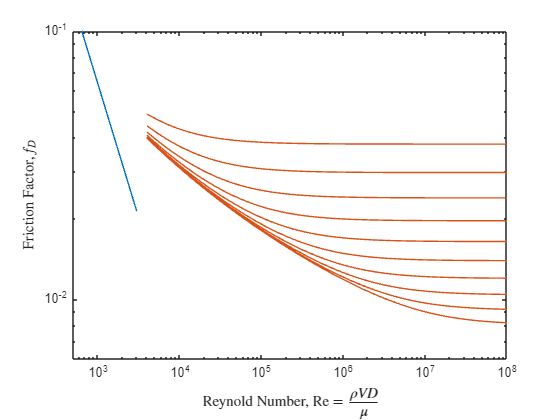

Re = logspace(log10(4000),8,100);
relativeRoughness = 0.000000005;
for rR = logspace(-5,-2,10)
    for i = 1:length(Re)
        Colebrook = @(f) 1/sqrt(f) + 2*log10(rR/3.7+2.51/(Re(i)*sqrt(f)));
        fD(i) = fzero( Colebrook, [eps,1]);
    end
    hold on
    loglog(Re,fD,SeriesIndex=2)
    hold off
end
xlim([5e2 1e8])
ylim([6e-3 1e-1])

 **Exercise. Which line represent **

## A little bit of practise...

In this section, we are focusing on a standard house plumbing:

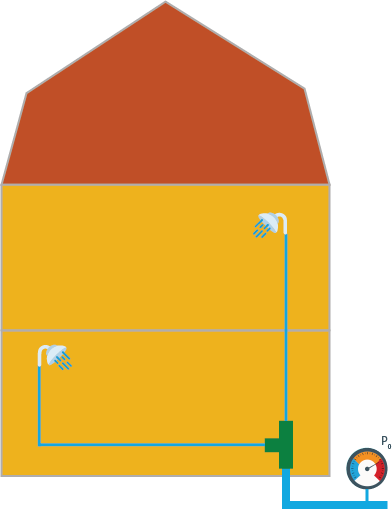

The main water intake line:

- Pipe diameter: 2 inches

- 90$^\circ$ elbow

First floor shower:

- 3/4" copper pipe 

- 90$^\circ$ elbow

Second floor shower:

- 1/2" copper pipe

 **Exercise. **What part of the system create headloss?

 **Exercise. **Estimate common headloss coefficient

% "Use encryption to be sure that figuring out the head loss is easier than
% cheating

Problems parameters:

- The water intake pipe is 30 ft long from the street

- The public water is pressurized at 50 psi

- The first floor shower head is located 4 m above the water intake pipe

- The second floor shower is located 7 m above the water intake pipe

- Both shower head pipe are located 25 feet away from the T-junction

- The water intake pipe dimeter is 2 inches

- The indoor water line are both using 1/2 inch pipping

  **Try. **Open the model

% The model should have instruction on what to do
rho = 1000;
gravity = 9.81;
intakeDiameter = 2;
intakeLength = 30;
indoorDiameter = 0.5;
indoorLength = 25;
elevation = [4 7];
open("HousePipe.slx")

 **Exercise. **Finalize 

% Check that the model is complete and give right answer

 **Exercise. **How could we make sure that the 2 shower flows the same way?

  **Try. **Open more complex model with toilet

 **Exercise. **Complete the following sentence:

Upon flushing, increase/decrease the hot/cold flow going to the shower head, therefore the water temperature should increase/decrease.

 **Exercise. **Can you think of a way to mitigate the effect of flushing?

open("HousePipeWithToilet.slx")

[⇦ Return to the navigation page](matlab:open('./Overview.html'))

Copyright 2023 The MathWorks™, Inc